## Очищення середовища

clear, close all

## 1. Завантаження зображень

% Кольорові зображення
image1_color = imread('peppers.png');
image2_color = imread('onion.png');

% Чорно-білі зображення
image3_gray = imread('cameraman.tif');
image4_gray = imread('coins.png');

## 2. Перетворення кольорових у чорно-білі

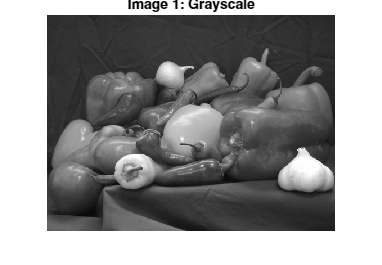

image1_gray = rgb2gray(image1_color);
image2_gray = rgb2gray(image2_color);

% Відображення
figure, imshow(image1_gray), title('Image 1: Grayscale');

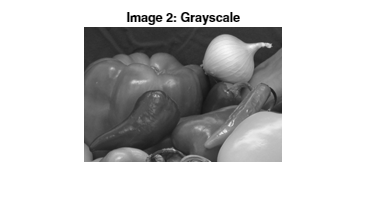

figure, imshow(image2_gray), title('Image 2: Grayscale');

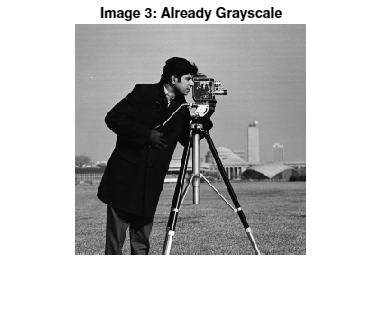

figure, imshow(image3_gray), title('Image 3: Already Grayscale');

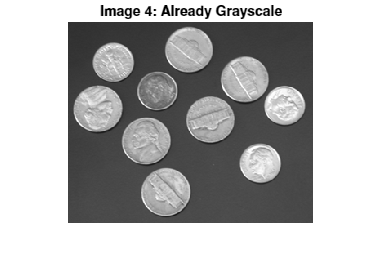

figure, imshow(image4_gray), title('Image 4: Already Grayscale');

## 3. Поблочне ДКП

T = dctmtx(8);
dct = @(block_struct) T * double(block_struct.data) * T';

% Функція для доповнення зображення до розміру, кратного 8
pad_to_multiple_of_8 = @(img) padarray(img, ...
    mod(8 - mod(size(img), 8), 8), 'post');

% Доповнюємо зображення
image2_padded = pad_to_multiple_of_8(image2_gray);
image4_padded = pad_to_multiple_of_8(image4_gray);

B1 = blockproc(image1_gray, [8 8], dct);
B2 = blockproc(image2_padded, [8 8], dct);
B3 = blockproc(image3_gray, [8 8], dct);
B4 = blockproc(image4_padded, [8 8], dct);

## 4. Відображення ДКП у логарифмічному масштабі

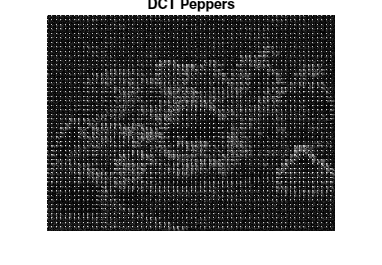

figure, imshow(log(abs(B1)+1), []), title('DCT Peppers');

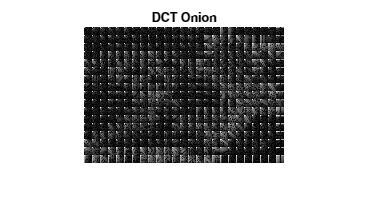

figure, imshow(log(abs(B2)+1), []), title('DCT Onion');

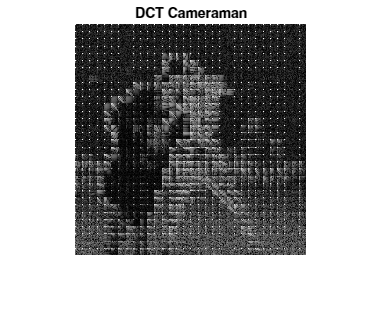

figure, imshow(log(abs(B3)+1), []), title('DCT Cameraman');

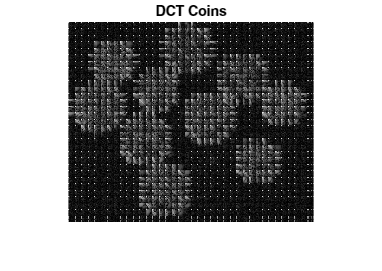

figure, imshow(log(abs(B4)+1), []), title('DCT Сoins');

**Пояснення:** Яскраво видно розподіл частот у кожному зображенні. Яскраві плями — домінуючі частоти в кожному блоці.

## 5. Відновлення зображень за ДКП

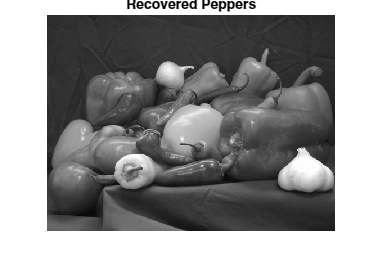

invdct = @(block_struct) T' * block_struct.data * T;

I1 = blockproc(B1, [8 8], invdct);
I2 = blockproc(B2, [8 8], invdct);
I3 = blockproc(B3, [8 8], invdct);
I4 = blockproc(B4, [8 8], invdct);

figure, imshow(uint8(I1)), title('Recovered Peppers');

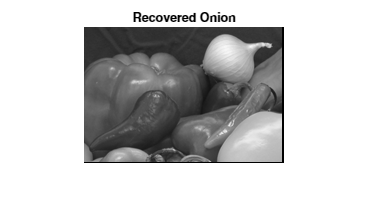

figure, imshow(uint8(I2)), title('Recovered Onion');

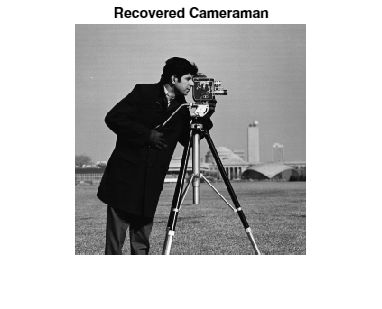

figure, imshow(uint8(I3)), title('Recovered Cameraman');

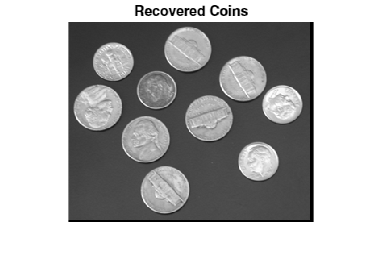

figure, imshow(uint8(I4)), title('Recovered Coins');

## 6. Квантування ДКП

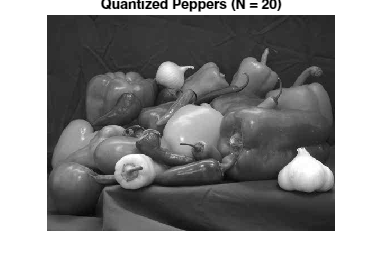

N = 20; 
B1q = N * round(B1 / N);
B2q = N * round(B2 / N);
B3q = N * round(B3 / N);
B4q = N * round(B4 / N);

I1q = blockproc(B1q, [8 8], invdct);
I2q = blockproc(B2q, [8 8], invdct);
I3q = blockproc(B3q, [8 8], invdct);
I4q = blockproc(B4q, [8 8], invdct);

figure, imshow(uint8(I1q)), title(['Quantized Peppers (N = ', num2str(N), ')']);

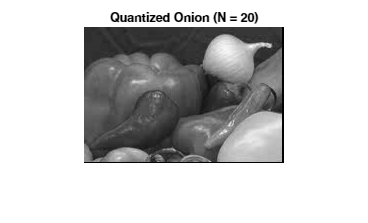

figure, imshow(uint8(I2q)), title(['Quantized Onion (N = ', num2str(N), ')']);

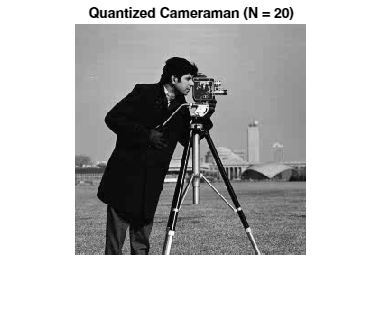

figure, imshow(uint8(I3q)), title(['Quantized Cameraman (N = ', num2str(N), ')']);

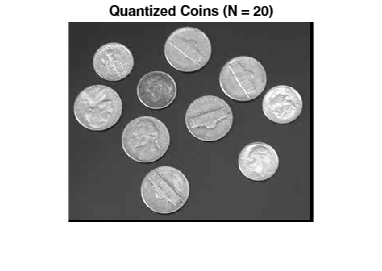

figure, imshow(uint8(I4q)), title(['Quantized Coins (N = ', num2str(N), ')']);

#### Пояснення: 

    При більшому квантуванні зображення стає менш чітким, але стискується краще — втрачаються малозначущі деталі.

## 7-8. Маскування високих частот

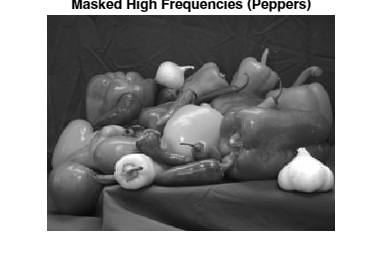

mask = [1 1 1 1 0 0 0 0;
        1 1 1 0 0 0 0 0;
        1 1 0 0 0 0 0 0;
        1 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0;
        0 0 0 0 0 0 0 0];

B1_masked = blockproc(B1, [8 8], @(block_struct) mask .* block_struct.data);
I1_masked = blockproc(B1_masked, [8 8], invdct);

figure, imshow(uint8(I1_masked)), title('Masked High Frequencies (Peppers)');

## 9. Пояснення

Маскування та квантування дозволяють зберегти лише значущі низькочастотні компоненти, що забезпечує ефективне стиснення зображення зі зменшенням деталізації.

Це є основою алгоритмів стиснення, таких як JPEG.